Loads protein/eve2 traces (run from src)

trace_struct_final1 = load('../dat/Kruppel_eve2_C/inference_traces_Kruppel_eve2_C_dT20.mat', 'trace_struct_final');
trace_struct_final1 = trace_struct_final1.trace_struct_final;

trace_struct_final2 = load('../dat/Kruppel_eve2_A/inference_traces_Kruppel_eve2_A_dT20.mat', 'trace_struct_final');
trace_struct_final2 = trace_struct_final2.trace_struct_final;

trace_struct_final = [trace_struct_final1 trace_struct_final2];

View trace i

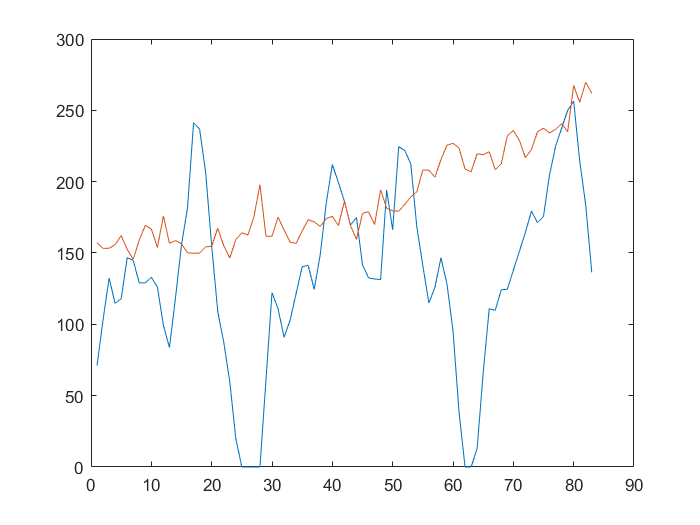

i = 58;
figure();
plot(trace_struct_final(i).fluo_interp)
hold on
plot(trace_struct_final(i).protein_interp)

Compute Cross Correlation

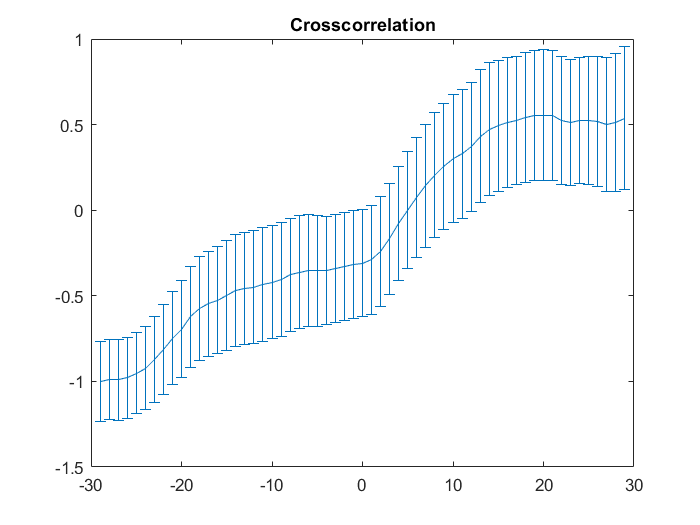

addpath('utilities/');
traces = cell(1,1);
proteins = cell(1,1);
k = 1;
for j = 1:length(trace_struct_final)
    if length(trace_struct_final(j).fluo_interp) > 40
        traces{k} = trace_struct_final(j).fluo_interp;
        proteins{k} = trace_struct_final(j).protein_interp;
        k = k + 1;
    end
end
max_delay = 30;
corr = cross_corr_m_calc(traces, proteins, 30);
deriv1 = corr(2:end) - corr(1:end-1);
deriv2 = deriv1(2:end) - deriv1(1:end-1);
[stds, stds1, stds2] = corr_bootstraps(traces,proteins,30,150,'m');


figure();
%plot(-max_delay + 1:max_delay - 1, corr)
errorbar(-max_delay + 1:max_delay - 1, corr, stds);
title('Crosscorrelation')

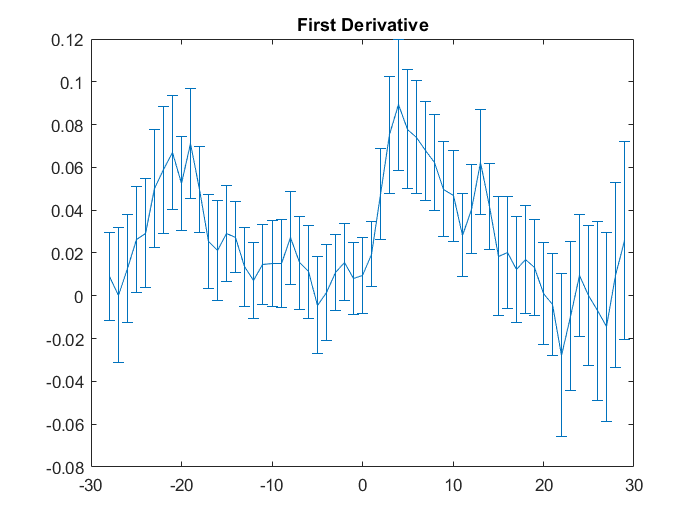


figure();
%plot(-max_delay + 2: max_delay - 1, deriv1);
errorbar(-max_delay + 2: max_delay - 1, deriv1, stds1);
title('First Derivative');

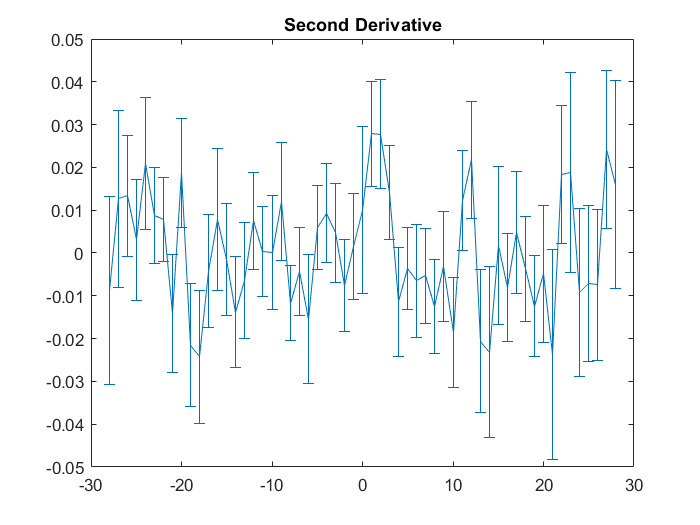


figure();
%plot(-max_delay + 2: max_delay - 2, deriv2);
errorbar(-max_delay + 2: max_delay - 2, deriv2, stds2);
title('Second Derivative');